# HIL Simulation of a Shipboard Power System

## Description

This reference application demonstrates how to perform model-in-the-loop (MIL) and hardware-in-the-loop (HIL) simulation of a two-zone medium voltage direct current (MVDC) shipboard power system. The shipboard power system plant is modeled with Simscape Electrical and it is based on *MathWorks Shipboard Power System in Simscape* example [1].

The MVDC architecture with 12kV DC represents a departure from traditional 60Hz AC shipboard power systems. This shift allows for improved power density and quality. Some key modeling aspects of the included shipboard power system plant include:

- Utilization of ideal AC/DC rectifiers

- Power sharing enabled through voltage droop controls

- The Power Motor Module is represented in the model as a permanent magnet synchronous machine (PMSM) controlled using a Field-Oriented Control (FOC) technique while employing an average-value converter

- The generators in the system are modeled as salient-pole synchronous machines equipped with AC1A voltage control and GAST turbines.

### **    Learn How To:**

- Model a real-time capable digital twin of a 12kV MVDC shipboard power system

- Explore benefits of multi-rate and multi-domain real-time simulation 

- Seamlessly transition from MIL to HIL within Simulink without changing your model 

- Interface the shipboard digital twin with a shipboard PLC controller using Modbus TCP

- Perform interactive HIL testing with Simulink and MATLAB

## **Supported Model-based Design Use Cases **

This example supports the following simulation modes (see image below):

- Desktop MIL: Both the shipboard plant and controllers run on the development computer. Use this simulation mode to test and verify controls (e.g., voltage droop, FOC) and shipboard power system in closed-loop desktop simulation.

- Real-time MIL: Both the shipboard plant and  controllers run in real-time on a Speedgoat HIL test system. Use this mode to validate real-time simulation aspects. The development computer is used to control the simulation, fine-tune plant and controller parameters, and measure and record real-time data.

- HIL: Reuse the model to generate Structured Text from voltage droop logic and deploy it onto a SIEMENS PLC controller. Extend the shipboard plant with fieldbus I/O such as Modbus TCP. Validate fieldbus communication in real-time by interfacing the PLC controller against the shipboard digital twin running on Speedgoat hardware. Perform interactive and automated HIL testing.

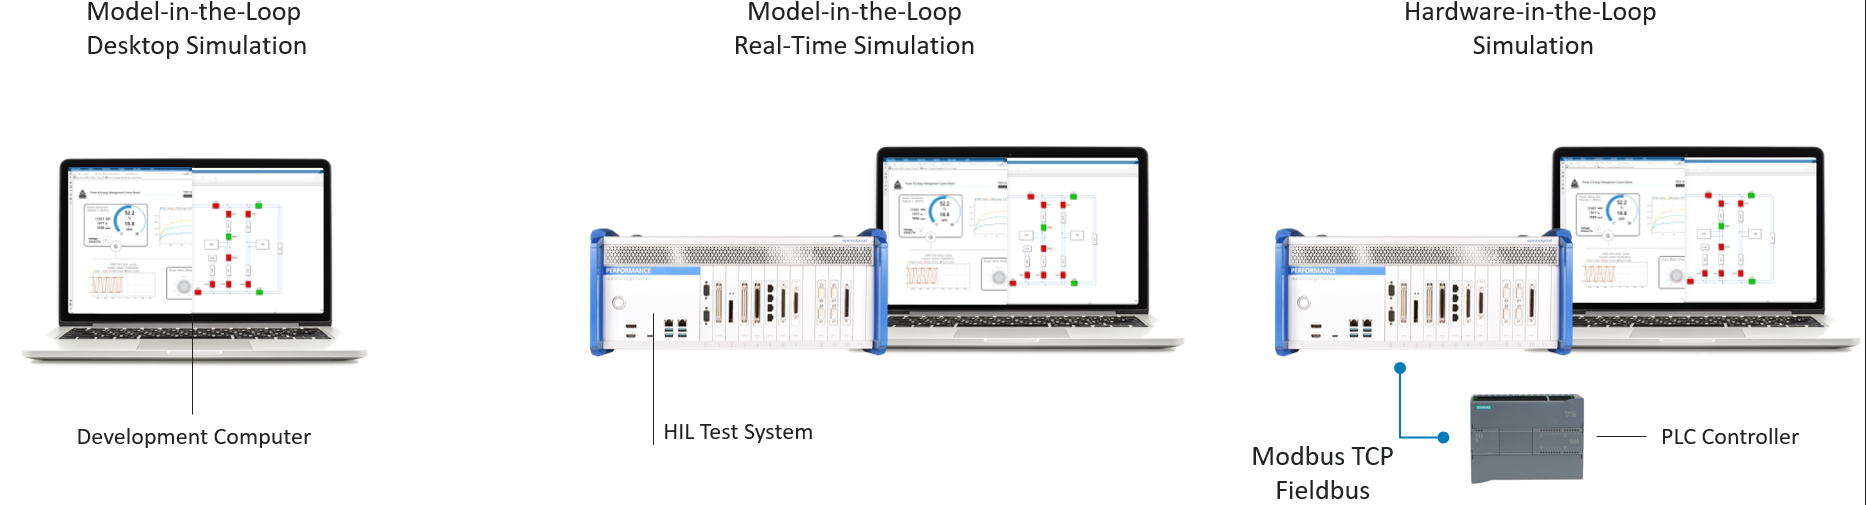

## System Requirements

###     MathWorks Products

-  [Simulink Real-Time™](https://www.mathworks.com/products/simulink-real-time.html)

-  [Simscape Electrical™](https://www.mathworks.com/products/simscape-electrical.html)

###     Speedgoat Products

-   [Performance Real-Time Target Machine](https://www.speedgoat.com/products-services/real-time-target-machines/performance-real-time-target-machine)

-   [MODBUS RTU and TCP Master/Slave Protocol for Simulink](https://www.speedgoat.com/products-services/i-o-connectivity/protocols/modbus-tcp)

## Testbench Configuration 

### **    Configure Testbench for  MIL Simulation**

mdl = 'ShipboardPMSHIL';
open_system(mdl);
switchConfig(mdl,'MIL'); 

### **    Configure Testbench for HIL Simulation**

mdl = 'ShipboardPMSHIL';
open_system(mdl);
switchConfig(mdl,'HIL'); 

### **    Set Up PLC Controller**

- This project has been set up to work with two different Siemens PLC models: S7-1211C and S7-1214C.  The configuration files for those two PLCs are stored in designated folders separately.  Locate the PLC project file (‘ElectricShipPLC.ap17’) for the Siemens PLC that you will use within project folder (1211C or 1214C).  The following scripts helps to locate the folder (user to pick the PLC model #)

p = slproject.getCurrentProject;
projectRoot = p.RootFolder;
supportFilesFolder = fullfile(projectRoot,'support_files\source_files\ElectricShipPLC\PLC1214C'); %for S7-1214C PLC
% supportFilesFolder = fullfile(projectRoot,'support_files\source_files\ElectricShipPLC\PLC1211C'); %for S7-1211C PLC
eval(['cd ' supportFilesFolder]);

            2. Open and build PLC project in Siemens TIA Portal (V17).  The project file is 'ElectricShipPLC.ap17’.

    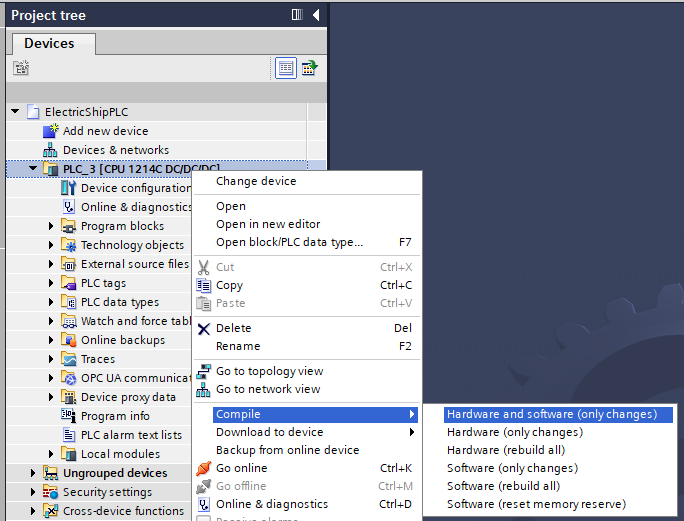

            3. Download compiled project to PLC and "Go Online"

    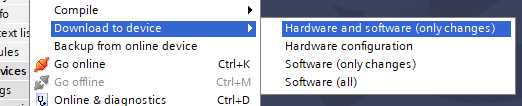

At this stage, the PLC is running and users can run the Simulink model on target machine now.

### **    Set Up HIL Test System**

mdl = 'ShipboardPMSHIL'
open_system(mdl);
switchConfig(mdl,'HIL');

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Build the Simulink model
slbuild(mdl);   
  
% Download and install the real-time application on the target machine
tg.load(mdl);
  
% Start simulation of real-time application
tg.start;

### **    PLC- HIL Test System Conectivity Settings**

The example uses the following IP addresses for the PLCs:

- PLC1214C: 192.168.0.1

- PLC1211C: 172.21.200.16

## **Exercises**

### **    Exercise 1: Exploring Multi-Domain, Multi-Rate, and Multi-Core Simulation **

- **Simulation of Multi-rate and Multi-Domain Simscape Models**                     

Simscape enables multidomain (e.g., electrical, thermal, and mechanical) simulation which is crucial for HIL simulation, where interactions between various domains need to be accurately represented to emulate real-world conditions. One common challenge is dealing with systems that operate at different rates. For example, a power electronics system may have a faster dynamics compared to the mechanical system it controls. With Simscape each domain can get its respective rate within the same simulation environment. This allows for the seamless integration of multiple rates and ensures that the interactions between different domains are faithfully captured by the HIL simulation.                                                                                                                                                                                                                                                                                

The figure below outlines the thermal and cooling models for the circuit of the PMSM used in the shipboard Power Motor Module. These models expose three different physical domains: thermal, hydraulic, and mechanical.

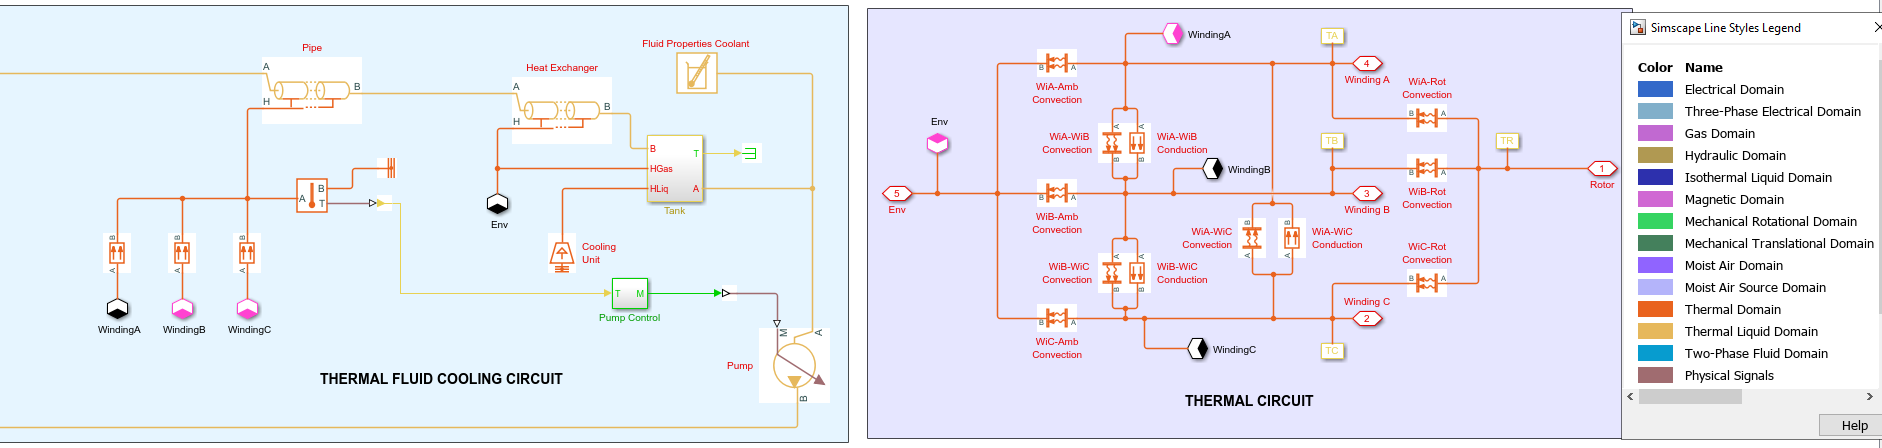

The figure below outlines solver configuration for the thermal (left) and electrical (right) Simscape networks, which run at different rates:

- The electrical physical domain runs at the fastest rate,  40kHz, thus enabling the capture of fast dynamics, while

- the thermal physical domain, which has slower time constants, runs at 1kHz

.

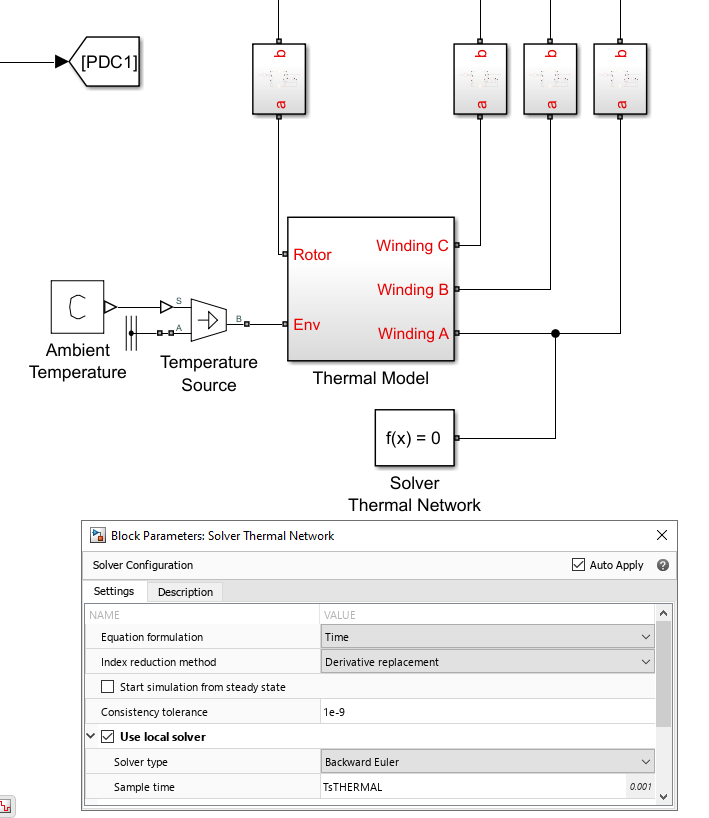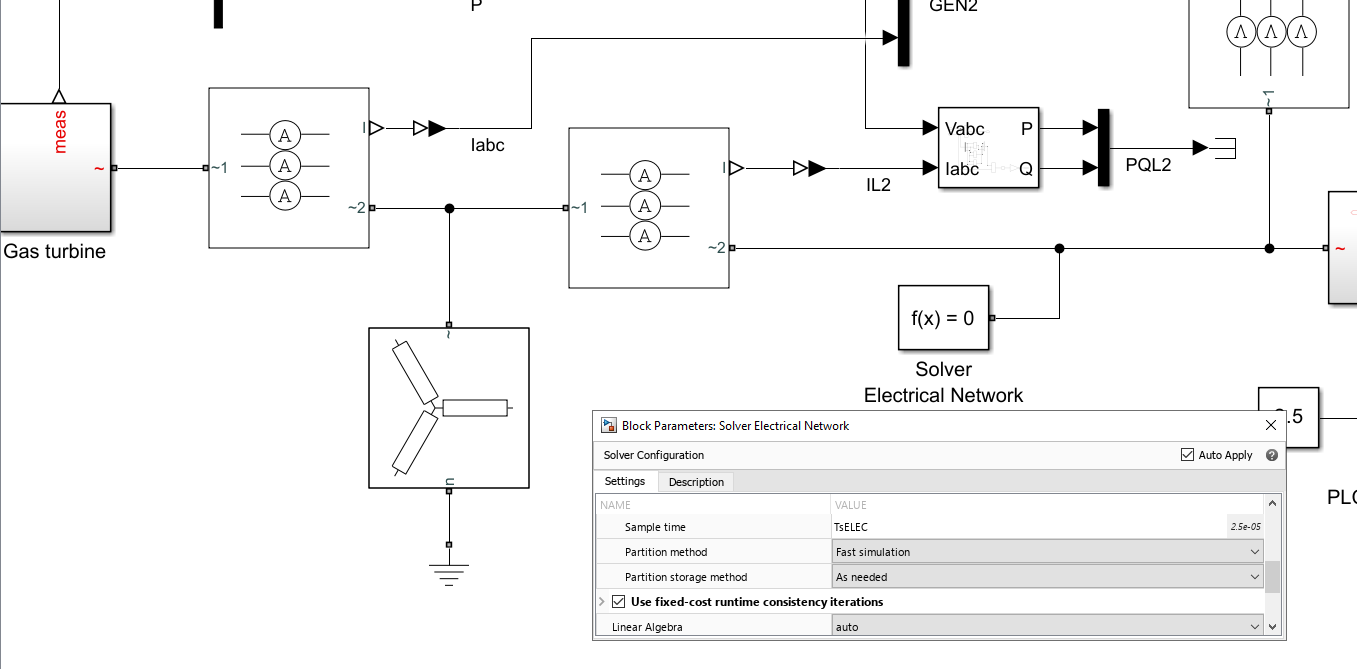

- **Concurrent and Multi-Target Execution of Shipboard Power Systems**

Simulink Real-Time supports concurrent execution by using implicit partitioning or explicit partitioning of models. The automated way of creating concurrent tasks and mapping them to your HIL test system multicores is called implicit partitioning. In this mode, Simulink partitions your model based on the sample time of blocks at the root level. Each sample time in your model corresponds to a partition, and all blocks of a single rate or sample time belong to the same partition. Simulink maps these partitions to tasks that run on your HIL processor. 

The picture below outlines the execution time information of a HIL real-time run leveraging three cores, for the electrical (40kHz), thermal (1kHz), and instrumentation (100Hz) simulation rates.

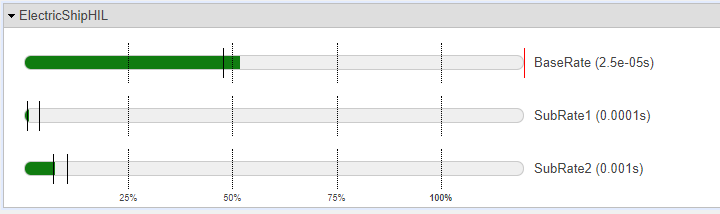

Learn more: [Concurrent Execution on Simulink Real-Time ](https://ch.mathworks.com/help/slrealtime/ug/concurrent-execution-on-simulink-real-time.html)

You can also specify how to partition your model, using explicit partitioning. In explicit partitioning, you create partitions in the root-level model by using referenced models, MATLAB system blocks, MATLAB Function blocks, Stateflow charts, and Simulink subsystems. You can further optimize and scale up the shipboard power system simulation using multi-target simulation with high-speed data interconnects such as [shared memory](https://www.speedgoat.com/products-services/i-o-connectivity/shared-memory).

Learn more:[Marine Power Systems with HIL-Testing](https://www.speedgoat.com/knowledge-center/webinars/advancing-marine-power-systems-using-hardware-in-the-loop-testing)

### **    Exercise 2: **Power Sharing Using Voltage Droop

- **Power Sharing Control**

Tune voltage droop to control power sharing between the two power generators modules.

Scenario 1:

- PGM1 voltage droop = 5%

- PGM 2 voltage droop= 2.5%

PGM 2 produces twice as much power as PGM 1, as droop of PGM 2 is half of PGM 1.

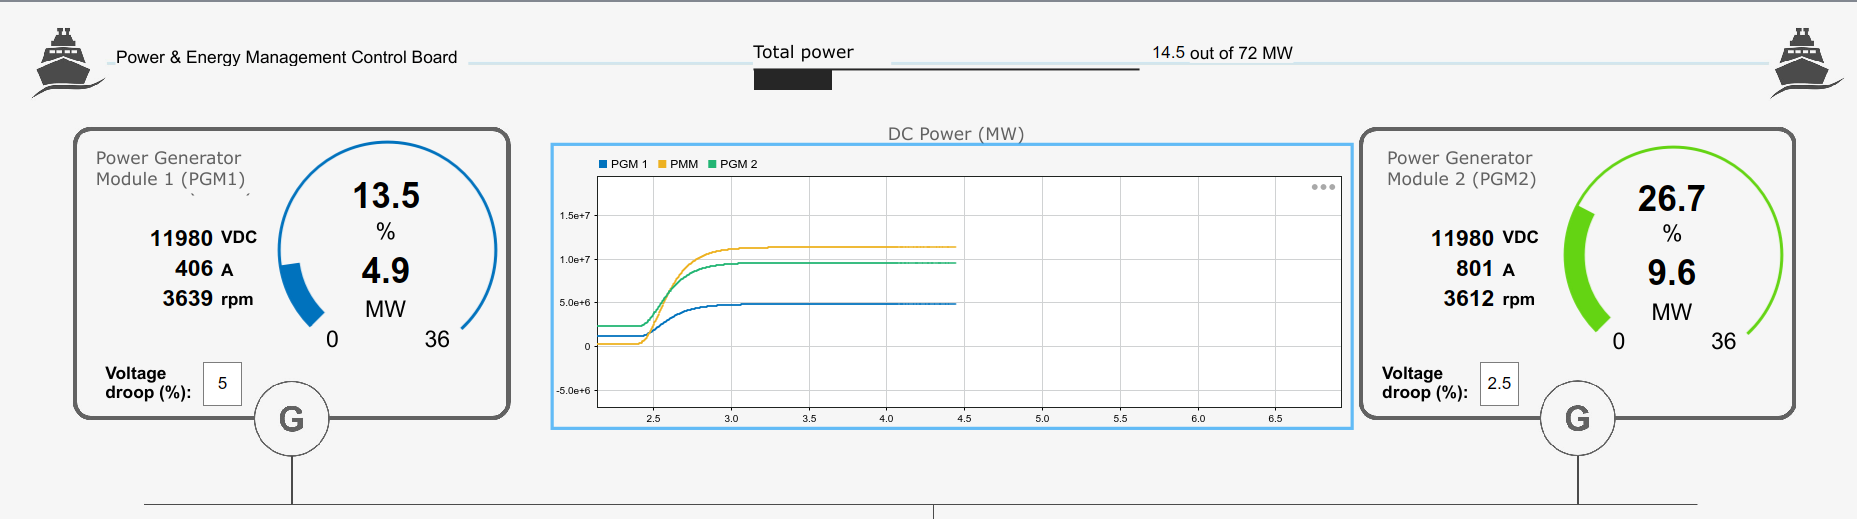

Scenario 2:

- PGM1 voltage droop = 5%

- PGM 2 voltage droop= 5%

PGM 2 and PGM 1 produce same amount of power. 

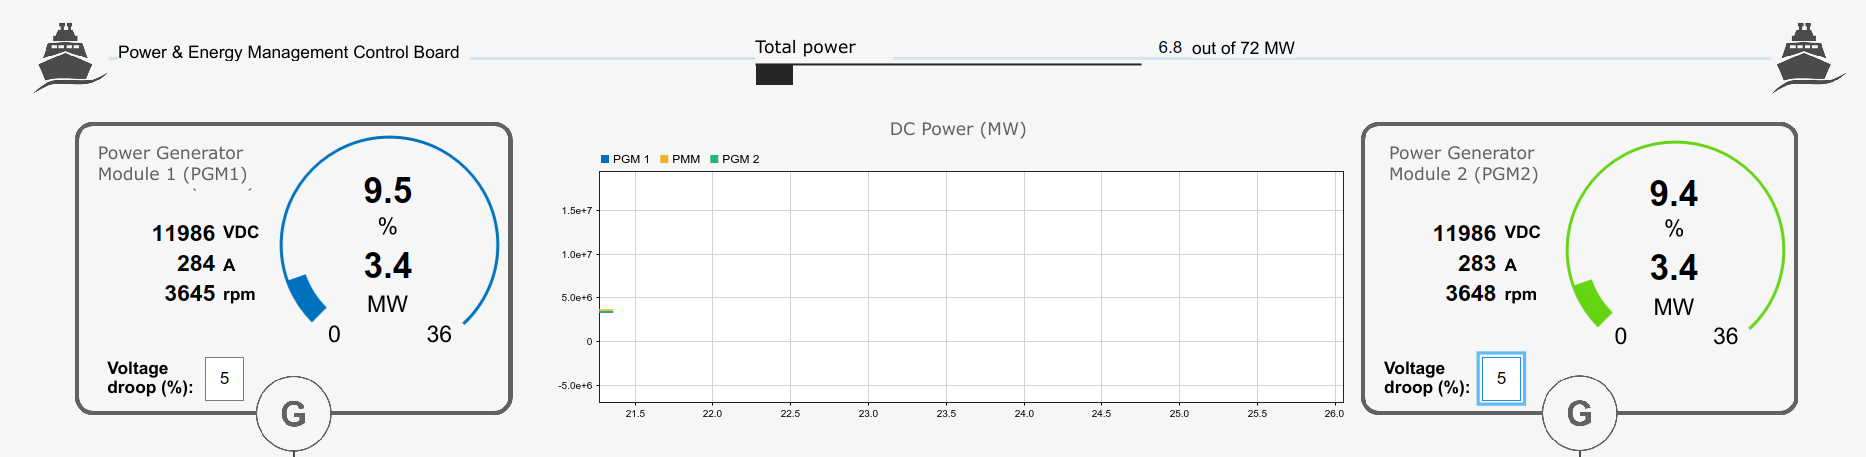

- **DC Voltage Regulation**

Regardless of the voltage droop parameters used, DV voltage is kept constant ~12kV.

 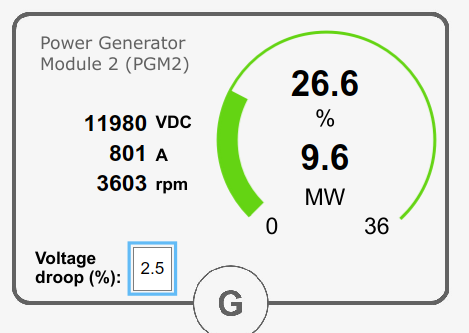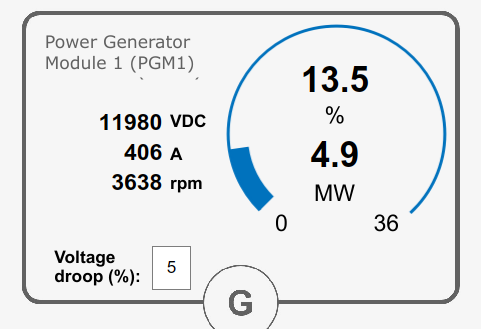

### **    Exercise 3: Fine Tuning Power Module FOC PI Controller  **

- **FOC Speed PI Controller Regulation**

Tune speed PI controller gain and observe the difference in the controller performances.

Default PI values: P = 500, I = 2000.

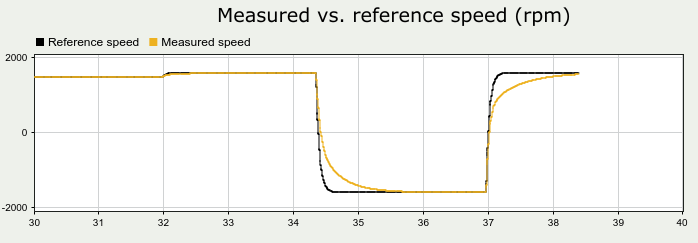

Scenario 1:

- P = 500;

- I= 0;

## 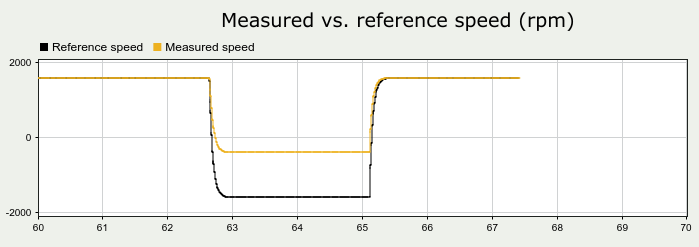

Scenario 2:

- P = 3000;

- I= 2000;

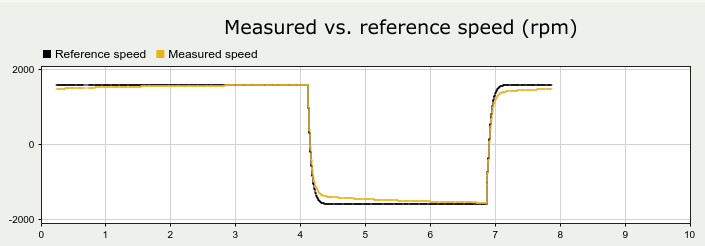

## Related Content

- [Shipboard Power System in Simscape](https://www.mathworks.com/matlabcentral/fileexchange/76995-shipboard-power-system-in-simscape)

- [Electric Ship Modeling and Simulation Video](https://www.mathworks.com/videos/electric-ship-modeling-and-simulation-1595333464416.html)

- [Marine Power System Deployment to HIL](https://www.mathworks.com/help/sps/ug/marine-power-system.html)

- [Speeding up Electrical System Simulations on Desktops and HiL with Simscape](https://www.mathworks.com/videos/speeding-up-electrical-system-simulations-with-simscape-1625166437570.html?s_tid=srchtitle)

## References

[1] [Shipboard Power System in Simscape](https://mathworks.com/matlabcentral/fileexchange/76995-shipboard-power-system-in-simscape?s_tid=srchtitle): Graham Dudgeon (2023). Shipboard Power System in Simscape (https://github.com/mathworks/Two-Zone-MVDC-Electric-Ship), GitHub. Retrieved June 5, 2023.

## Release Notes

open README.md
